**Finite Difference Methods for Elliptic PDEs**

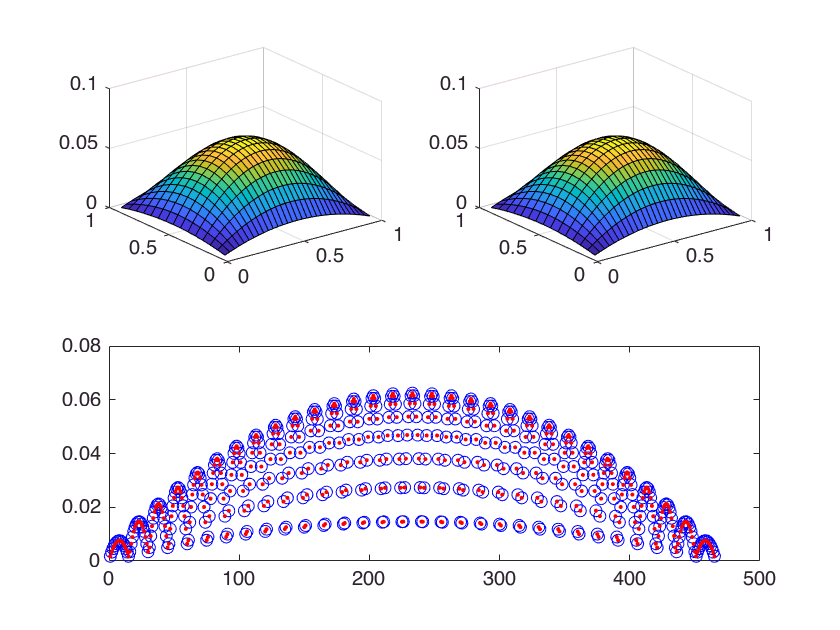

close, clear, clc

bx = [0, 1];
by = [0, 1];
N_x = 32;
N_y = 16;


tic
Au = @(x, y)(x.*y.*(x-1).*(y-1));
f = @(x, y)(-(2*x*cos(x*y*(x - 1)*(y - 1))*(x - 1) - sin(x*y*(x - 1)*(y - 1))*(x*y*(y - 1) + y*(x - 1)*(y - 1))^2 - sin(x*y*(x - 1)*(y - 1))*(x*y*(x - 1) + x*(x - 1)*(y - 1))^2 + 2*y*cos(x*y*(x - 1)*(y - 1))*(y - 1)));
u1 = Poisson_2D_FD_rectangle_dirichlet( bx, by, N_x, N_y, Au, f );

toc

时间已过 0.472510 秒。


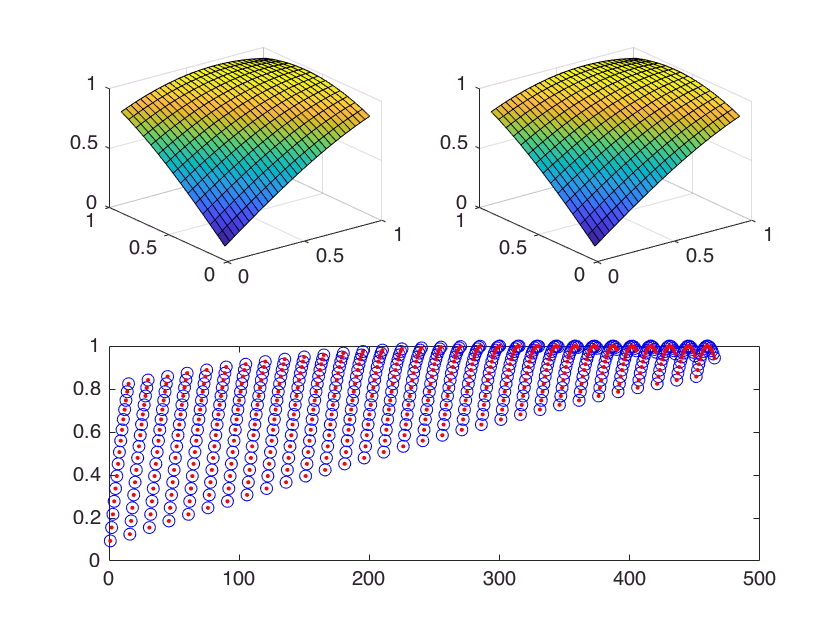

tic
Au1 = @(x, y)(sin(x+y));
f1 = @(x, y)(2*sin(x + y));
u2 = Poisson_2D_FD_rectangle_dirichlet( bx, by, N_x, N_y, Au1, f1 );

toc

时间已过 0.472340 秒。
